# **Greedy Kernel PCA Applied to EEG Preprocessing**

## **Step 1: Load DREAMER dataset**

disp('----------LOAD DREAMER DATASET----------');

----------LOAD DREAMER DATASET----------


% Absolute directory to dataset
load('E:/Capstone-Project/human-emotion-recognition-based-on-eeg/dataset/dreamer/DREAMER.mat');

% "DREAMER" variable is available when dataset have already been loaded
disp(DREAMER);

                  Data: {1×23 cell}
      EEG_SamplingRate: 128
      ECG_SamplingRate: 256
        EEG_Electrodes: {'AF3'  'F7'  'F3'  'FC5'  'T7'  'P7'  'O1'  'O2'  'P8'  'T8'  'FC6'  'F4'  'F8'  'AF4'}
          noOfSubjects: 23
    noOfVideoSequences: 18
            Disclaimer: 'While every care has been taken to ensure the accuracy of the data included in the DREAMER dataset, the authors and the University of the West of Scotland dataset do not provide any guarantees and disclaim all responsibility and all  liability (including without limitation, liability in negligence) for all expenses, losses, damages (including indirect or consequential damage) and costs which you might incur as a result of the provided data being inaccurate or incomplete in any way and for any reason. 2017, University of the West of Scotland, Scotland, United Kingdom'
              Provider: 'University of the West of Scotland'
               Version: '1.0.2'
       Acknowledgement: 'The authors would like t

## Step 2: Preprocessing

### Frequency domain filter

- Bandpass filter

Select alpha and beta waves only.

For example, let filter the EEG signal in P8 channel of the first volunteer

disp('----------PREPROCESSING----------');

----------PREPROCESSING----------


disp('----------Frequency fomain filter----------');

----------Frequency fomain filter----------


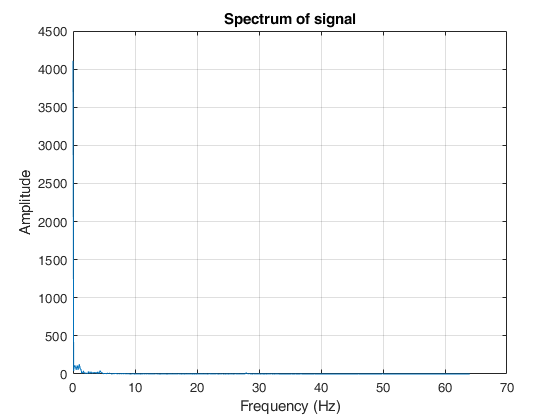

% Signal before being filtered
rawEEGSignal = DREAMER.Data{1, 1}.EEG.baseline{1, 1}(1:1280, getEEGChannelIndex('F3'));
signalFrequencyAnalyzer(rawEEGSignal, DREAMER.EEG_SamplingRate);

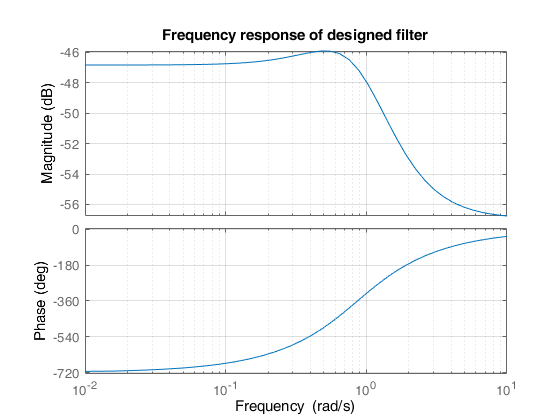


% Apply bandpass filter to this section
filteredEEGSignal = eegFilter(rawEEGSignal, DREAMER.EEG_SamplingRate);

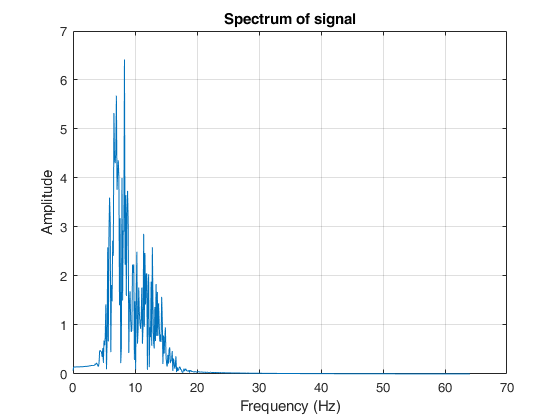

signalFrequencyAnalyzer(filteredEEGSignal, DREAMER.EEG_SamplingRate);

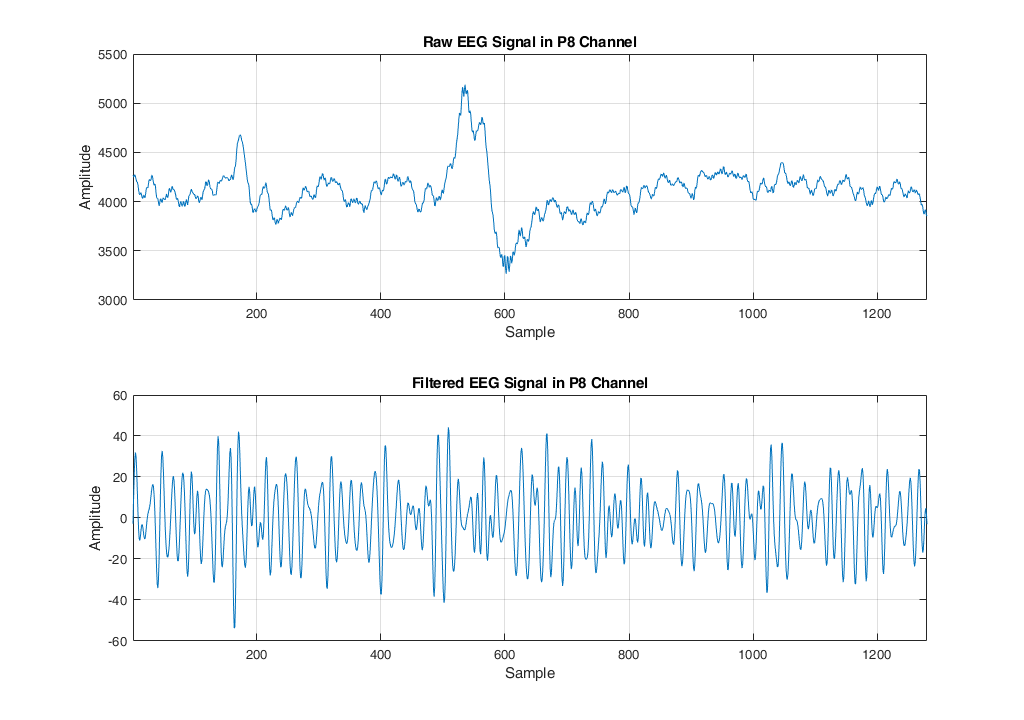


figure('NumberTitle', 'off', 'Name', 'EEG Signal', 'Position', [0, 0, 1024, 720]);

subplot(2, 1, 1);
plot(rawEEGSignal);
xlabel('Sample');
ylabel('Amplitude');
title('Raw EEG Signal in P8 Channel');
xlim([1, length(rawEEGSignal)]); 
grid on;

subplot(2, 1, 2);
plot(filteredEEGSignal);
xlabel('Sample');
ylabel('Amplitude');
title('Filtered EEG Signal in P8 Channel');
xlim([1, length(filteredEEGSignal)]); 
grid on;

### Data normalization

The filtered EEG signal still exists artifacts. So, Robust Normalization is applied for normalizing this data. 

The normalization formula is


$$X' = \frac{X-median(X)}{IRQ(X)}$$


where $IRQ(X)$ is interquartile range of input data.

disp('----------Data normalization----------');

----------Data normalization----------


normalizedData = robustNormalization(filteredEEGSignal);
disp(normalizedData);

   -0.1397
    0.4340
    0.9211
    1.2496
    1.3692
    1.2639
    0.9623
    0.5383
    0.0955
   -0.2619
   -0.4628
   -0.4935
   -0.3992
   -0.2621
   -0.1644
   -0.1539
   -0.2284
   -0.3432
   -0.4371
   -0.4622
   -0.4040
   -0.2838
   -0.1429
   -0.0203
    0.0652
    0.1201
    0.1677
    0.2329
    0.3285
    0.4486
    0.5713
    0.6657
    0.6993
    0.6433
    0.4757
    0.1874
   -0.2078
   -0.6628
   -1.0962
   -1.4068
   -1.5008
   -1.3258
   -0.8942
   -0.2870
    0.3672
    0.9297
    1.2923
    1.4034
    1.2743
    0.9644
    0.5566
    0.1326
   -0.2451
   -0.5392
   -0.7351
   -0.8342
   -0.8457
   -0.7811
   -0.6504
   -0.4611
   -0.2205
    0.0582
    0.3495
    0.6132
    0.8006
    0.8672
    0.7876
    0.5655
    0.2354
   -0.1445
   -0.5057
   -0.7840
   -0.9306
   -0.9206
   -0.7568
   -0.4687
   -0.1073
    0.2660
    0.5924
    0.8264
    0.9394
    0.9178
    0.7593
    0.4723
    0.0802
   -0.3704
   -0.8056
   -1.1321
   -1.2594
   -1.1323
   -0.7599

disp('The EEG data after applying Robust Normalization');

The EEG data after applying Robust Normalization


Verify the normalized data by distrubution diagram.

disp('----------Validate normalized data----------');

----------Validate normalized data----------


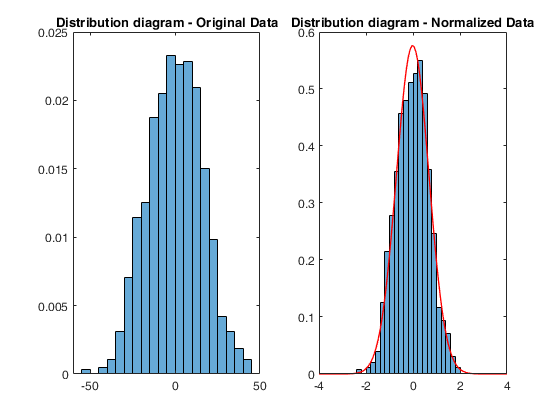

figure('NumberTitle', 'off');

subplot(1, 2, 1);
histogram(filteredEEGSignal, 'Normalization', 'pdf');
title('Distribution diagram - Original Data');

subplot(1, 2, 2);
histogram(normalizedData, 'Normalization', 'pdf');
title('Distribution diagram - Normalized Data');
hold on;
x = linspace(-4, 4, 100);
y = normpdf(x, mean(normalizedData), std(normalizedData));
plot(x, y, 'r-', 'LineWidth', 1);
hold off;

After normalization, the distribution diagram is symmetry and approximate normal distribution (the red line).

Finally, validate the corelation of data.

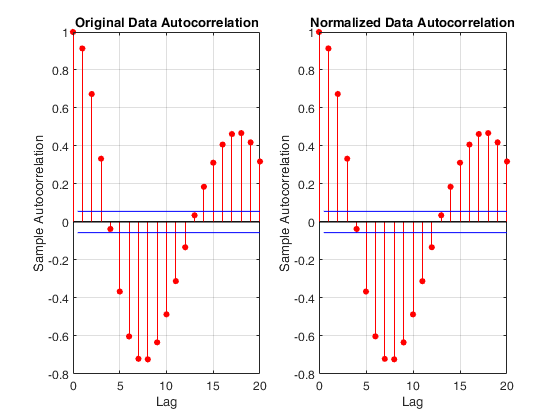

figure('NumberTitle', 'off');

subplot(1, 2, 1);
autocorr(filteredEEGSignal);
title('Original Data Autocorrelation');

subplot(1, 2, 2);
autocorr(normalizedData);
title('Normalized Data Autocorrelation');

## Step 3: Apply Kernel PCA

### Select Kernel and its parameters

Use RBF Kernel:


$$e^{-\frac{\|x-x'\|^2}{2\sigma ^ 2}}$$


where $\|x-x'\| $is Euclidean distance between data points, $\sigma$ is width of kernel.

 The $\sigma$ parameter should be tuned by using Median Trick method.

disp('----------APPLY KERNEL PCA----------');

----------APPLY KERNEL PCA----------


disp('----------Select Kernel and its parameters----------');

----------Select Kernel and its parameters----------


K = rbfKernel(normalizedData);
disp(K);

  Columns 1 through 13

    1.0000    0.9793    0.9873    0.9841    0.8366    0.7366    0.8646    0.9965    0.7106    0.4021    0.3710    0.6178    0.9599
    0.9793    1.0000    0.9990    0.9290    0.7250    0.6146    0.7581    0.9927    0.8242    0.5191    0.4847    0.7396    0.9967
    0.9873    0.9990    1.0000    0.9442    0.7507    0.6417    0.7830    0.9971    0.8008    0.4927    0.4589    0.7137    0.9921
    0.9841    0.9290    0.9442    1.0000    0.9162    0.8337    0.9371    0.9661    0.6032    0.3108    0.2838    0.5101    0.8976
    0.8366    0.7250    0.7507    0.9162    1.0000    0.9831    0.9983    0.7931    0.3629    0.1502    0.1339    0.2876    0.6770
    0.7366    0.6146    0.6417    0.8337    0.9831    1.0000    0.9710    0.6876    0.2743    0.1031    0.0909    0.2112    0.5654
    0.8646    0.7581    0.7830    0.9371    0.9983    0.9710    1.0000    0.8236    0.3933    0.1678    0.1500    0.3146    0.7113
    0.9965    0.9927    0.9971    0.9661    0.7931    0.687

disp(['Size of RBF Kernel matrix: ', num2str(size(K))]);

Size of RBF Kernel matrix: 1280  1280


The given data is non-linear mapped to higher dimensional space , called feature space. In feature space, PCA can be linear applied for this subspace.

### Eigen Decomposition

## Appendix

function value = getEEGChannelIndex(name)
    switch name
        case 'AF3'
            value = 1;
        case 'F7'
            value = 2;
        case 'F3'
            value = 3;
        case 'FC5'
            value = 4;
        case 'T7'
            value = 5;
        case 'P7'
            value = 6;
        case 'O1'
            value = 7;
        case 'O2'
            value = 8;
        case 'P8'
            value = 9;
        case 'T8'
            value = 10;
        case 'FC6'
            value = 11;
        case 'F4'
            value = 12;
        case 'F8'
            value = 13;
        case 'AF4'
            value = 14;
        otherwise
            error('Invalid EEG channel');
    end
end
%----------------------------------------------------------------------------------------------------------------------------%

%----------------------------------------------------------------------------------------------------------------------------%
% Butterworth bandpass filter
% 
% Inputs:   rawSignal - The raw signal
%           fSampling - Sampling rate (Hz)
%
% Output:   filteredSignal - The filtered signal
function filteredSignal = eegFilter(rawSignal, fSampling)
    % Filter parameters
    order = 4;
    fNyquist = fSampling/2;
    fCut = [6 15];
    
    % Design the filter
    [b, a] = butter(order, fCut/fNyquist, 'bandpass');
    
    % Frequency response of this filter
    sys = tf(b, a);
    
    figure;
    bode(sys);
    grid on;
    title('Frequency response of designed filter');
    
    % Apply filter
    filteredSignal = filtfilt(b, a, rawSignal);
end
%----------------------------------------------------------------------------------------------------------------------------%

%----------------------------------------------------------------------------------------------------------------------------%
% signalFrequencyAnalyzer - Analyze signal in frequency domain
%
% Inputs:   signal      - The input signal
%           fSampling   - Sampling rate (Hz)
% Output:   The frequency spectrum of signal
function signalFrequencyAnalyzer(signal, fSampling)
    % FFT
    N = length(signal);
    Y = fft(signal);
    P2 = abs(Y/N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = fSampling*(0:(N/2))/N;

    figure;
    plot(f, P1);
    title('Spectrum of signal');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;
end
%----------------------------------------------------------------------------------------------------------------------------%

%----------------------------------------------------------------------------------------------------------------------------%
% rbfKernel - Calculate RBF kernel matrix
%
% Inputs:   data        - The input matrix
% Output:   k           - The RBF kernel matrix
function k = rbfKernel(data)
    % Estimate sigma using Median Trick
    sigma = median(pdist2(data, data, 'euclidean'), 'all');
    
    % calculate kernel matrix
    k = exp(-pdist2(data, data, 'euclidean').^2 / (2 * sigma^2));
end
%----------------------------------------------------------------------------------------------------------------------------%

%----------------------------------------------------------------------------------------------------------------------------%
% robustNormalization - Normalize the data using Robust Scaling
%
% Inputs:   data            - The input data
% Output:   normalizedData  - The normalized data
function normalizedData = robustNormalization(data)
    Q25 = quantile(data, 0.25, 1);
    Q75 = quantile(data, 0.75, 1);
    IQR = Q75 - Q25 + 0.01; % Avoid divided by 0
    
    normalizedData = (data - median(data, 1)) ./ IQR;
end
%----------------------------------------------------------------------------------------------------------------------------%